# Lab 4: PCA-based Face Recognition

Submission : Blackboard, by 2:30PM on Wednesday, 26 September, 2018

## Dataset

We will use the ORL database, available to download on AT&T’s web site. This database contains photographs showing the faces of 40 people. Each one of them was photographed 10 times. These photos are stored as grayscale images with $112\times92$ pixels. 

In our example, we construct a catalog called `orlfaces`, comprised of people named $s_1, s_2, . . . , s_{40}$, each one of them containing 10 photographs of the person. The data has already been split into a training

clear
close all
% dir = 'orl_faces/Train/s10/%d.pgm'
% figure
% for i =1:9
%     subplot(1,9,i)
%     imshow(sprintf(dir,i));
% end    

 and testing split, where for each person, we use the first 9 photographs for training and the last photograph for test.

1. Load the training data

% Your code goes here
train_directory = 'orl_faces/Train/s%d/%d.pgm';
train_data = zeros(40,9,112,92);
for i = 1:40
    for j = 1:9
        image_name = sprintf(train_directory, i, j);
        train_data(i,j,:,:) = imread(image_name);
%         disp(image_name);
    end
end
size(train_data(1,1,:,:))

ans =      1     1   112    92


 2. Change each $(d_1, d_2) = (112, 92)$ photograph into a vector

% Your code goes here
image_size = size(train_data,3)*size(train_data,4);
train_reshape = reshape(train_data, [40, 9, image_size]);

size(train_reshape)

ans =           40           9       10304


3. Using all the training photographs for the $N$ people in the training dataset, construct a subspace $H$with dimensionality less than or equal to $N$such that this subspace has the maximum dispersion for the $N$ projections. To extract this subspace, use Principal Component Analysis, as described below - 

- Center the data

- Compute the correlation matrix

- Use either the `SVD` or `eig` functions to perform SVD and get the eigenvectors and eigenvalues for the correlation matrix.

- Normalize the eigenvectors by the corresponding eigenvalues.

% Your code goes here
typical_face = mean(mean(train_reshape, 1), 2);
train_difference_face  = zeros(40,9,10304);
for i = 1:40
    for j = 1:9
        train_difference_face(i,j,:) = (train_reshape(i,j,:) - typical_face);
    end    
end
train_center = double(reshape(train_difference_face, [], 10304));


corr_matrix = corr(train_center);
[e_vector, e_values] = eigs(corr_matrix, 360);

e_vector = real(e_vector);
e_values = abs(e_values);

disp('for easy calculation, use 360 for output')

4. Plot the eigenvalues

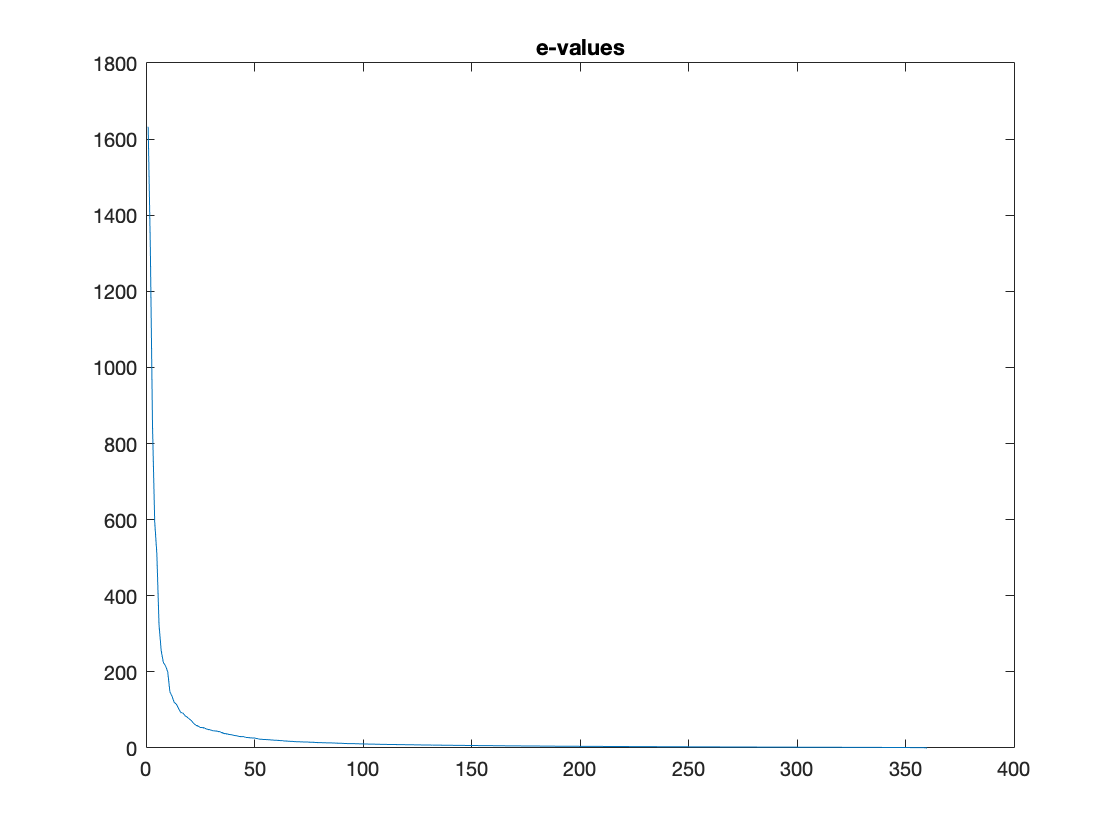

% Your code goes here
figure(1)
plot(diag(e_values)), title('e-values');

5. Plot the first 3 eigenfaces and the last eigenface (these will be the correctly reshaped eigenvectors)

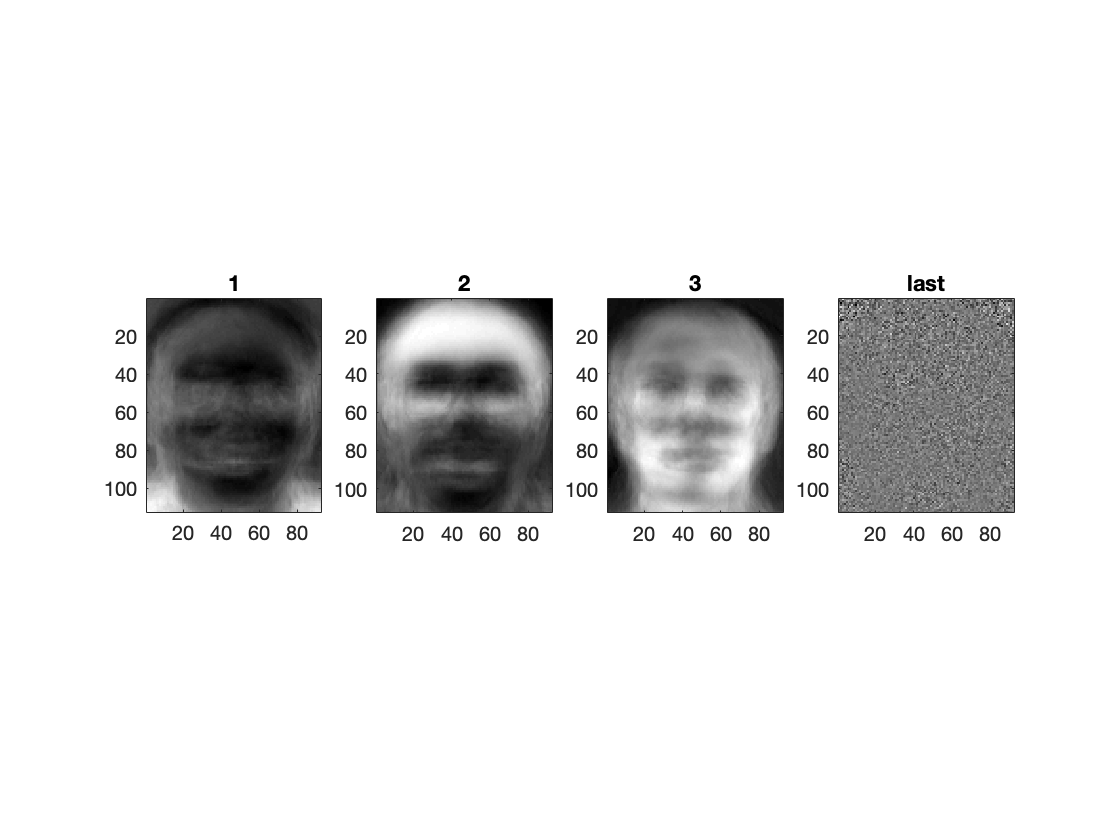

% Your code goes here 
figure(2)
subplot(1,4,1); imagesc(reshape(e_vector(:,1), 112,92)), title('1'),axis image, colormap gray; %imshow(mat2gray(reshape(e_vector(:,1),112,92))); 
subplot(1,4,2); imagesc(reshape(e_vector(:,2), 112,92)), title('2'),axis image, colormap gray;
subplot(1,4,3); imagesc(reshape(e_vector(:,3), 112,92)), title('3'),axis image, colormap gray;
subplot(1,4,4); imagesc(reshape(e_vector(:,end), 112,92)), title('last'),axis image, colormap gray;

6. Pick a face and reconstruct it using $k = {10, 20, 30, 40}$ eigenvectors. Plot all of these reconstructions and compare them. For each value of $k$, plot the original image, reconstructed image, and the difference b/w the original image and reconstruction in each case. Write your observations.

size(train_data)

ans =     40     9   112    92


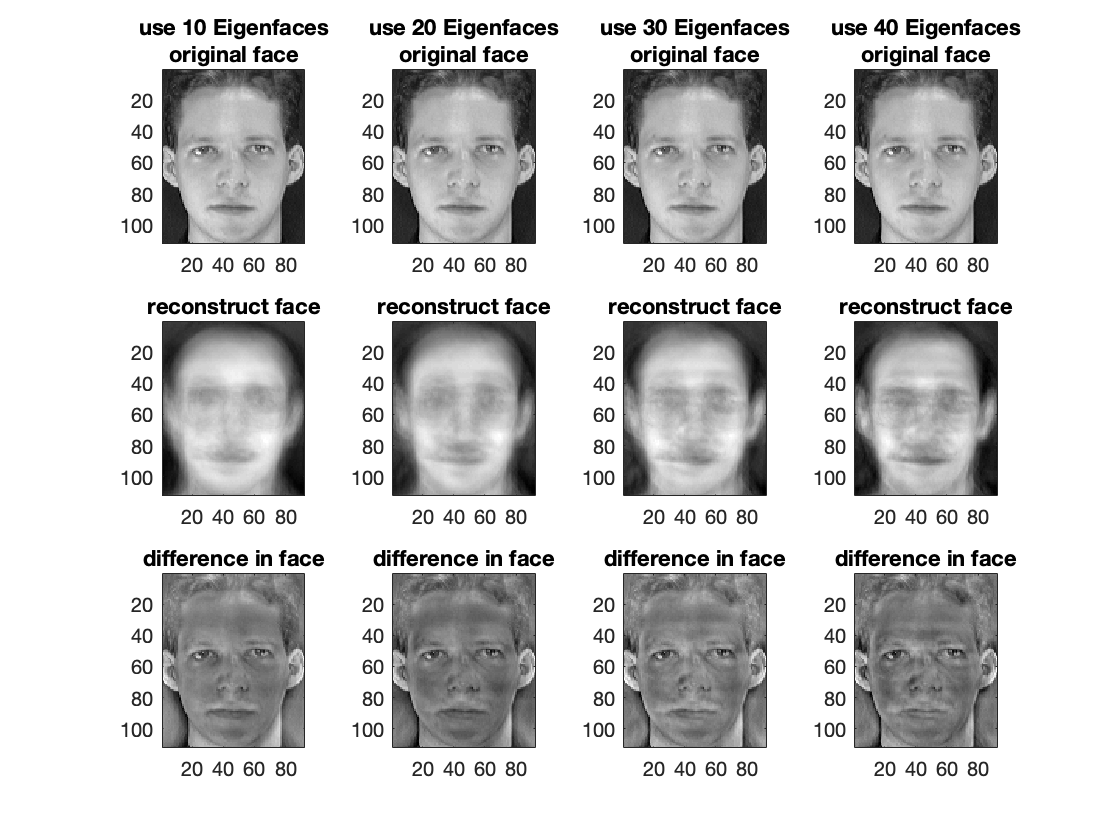

% Your code goes here
figure(3);
K_values = [10,20,30,40];
for i = 1:4
    B = e_vector(:,1:K_values(i));
    W = pinv(B) * double(reshape(train_difference_face(1,1,:),10304,1));
    image_approx = B * W;
    image_approx_rehape = reshape(image_approx, 112,92);
    typical_face_reshape = reshape(typical_face, 112,92);
    image_approx_face = image_approx_rehape + typical_face_reshape;
    image_approx_difference = reshape(train_data(1,1,:), 112,92) - image_approx_face;
    %plot
    subplot(3,4,i)
    imagesc(reshape(train_data(1,1,:), 112,92)), axis image, colormap gray, title({[sprintf('use %d Eigenfaces',K_values(i))], ['original face']});
    subplot(3,4,i+4)
    imagesc(image_approx_face), axis image, colormap gray, title('reconstruct face');
    subplot(3,4,i+8)
    imagesc(image_approx_difference), axis image, colormap gray, title('difference in face');

end

disp('as the k increases, the reconstruct face become much more clear, the difference become less')

as the k increases, the reconstruct face become much more clear, the difference become less


7. Load the testing data, and reshape it similar to the training data.

% Your code goes here
test_directory = 'orl_faces/Test/s%d/%d.pgm';
test_data = zeros(40,1,112,92);
for i = 1:40
        image_name = sprintf(test_directory, i, 10);
        test_data(i,1,:,:) = imread(image_name);
end

test_reshape = reshape(test_data, [40, 1, image_size]);

size(test_reshape)

ans =           40           1       10304


% Your code goes here
typical_face = mean(mean(train_reshape, 1), 2);
test_difference_face  = zeros(40,1,10304);
for i = 1:40
      test_difference_face(i,1,:) = (test_reshape(i,1,:) - typical_face);
        
end
test_center = double(reshape(test_difference_face, [], 10304));


8. For each photograph in the testing dataset, you will implement a classifier to predict the identity of the person. To do this, follow these steps - 

- Determine the projection of each test photo onto $H$ with different dimensionalities $d = {10, 20, 30, 40}$

- Compare the distance of this projection to the projections of all images in the training data.

- For each test photo's projection, find the closest category of projection in the training data.

% Your code goes here
figure(4)

d_values = [10,20,30,360];

p_test = zeros(40,4,10304);

for i = 1:4
    for j = 1:40 
         B1 = e_vector(:,1:d_values(i));
         W1 = pinv(B1) * double(reshape(test_difference_face(j,1,:),10304,1));
         image_approx1 = B1 * W1;
         p_test(j,i,:) = image_approx1;
    end     
end

p_train = zeros(360,4,10304);

K_values = [10,20,30,360];

train_difference_face2  = zeros(360,1,10304);
k360=1;
for i = 1:40
    for j = 1:9
         train_difference_face2(k360,1,:) = train_difference_face(i,j,:);
         k360 = k360+1;
    end
end    

for i = 1:4
    for j = 1:360
        B2 = e_vector(:,1:K_values(i));
        W2 = pinv(B2) * double(reshape(train_difference_face2(j,1,:),10304,1));
        image_approx2 = B2 * W2;
        p_train(j,i,:) = image_approx2;
    end
end

disp('distance is save in the error_result matrix')

distance is save in the error_result matrix



error_result=zeros(40,360,1);
for i = 1:40
    for j = 1:360

    error = bsxfun(@minus, p_test(i,4,:), p_train(j,4,:));
    error = sqrt(error.^2);
    error_result(i,j,1) = sum(error,3);

    end 
end

results = [];
for i = 1:40
    [minval, index] = min(error_result(i,:,1));
    results = [results, index];
end    


results

results =      5    16    27    32   356    49    58    66    77    66    91   108   113   123   128   138   151   161   163   173   188   191   199   216   219   233   235   246   255   262   275   285   290   306   311   321   333   338   348    37


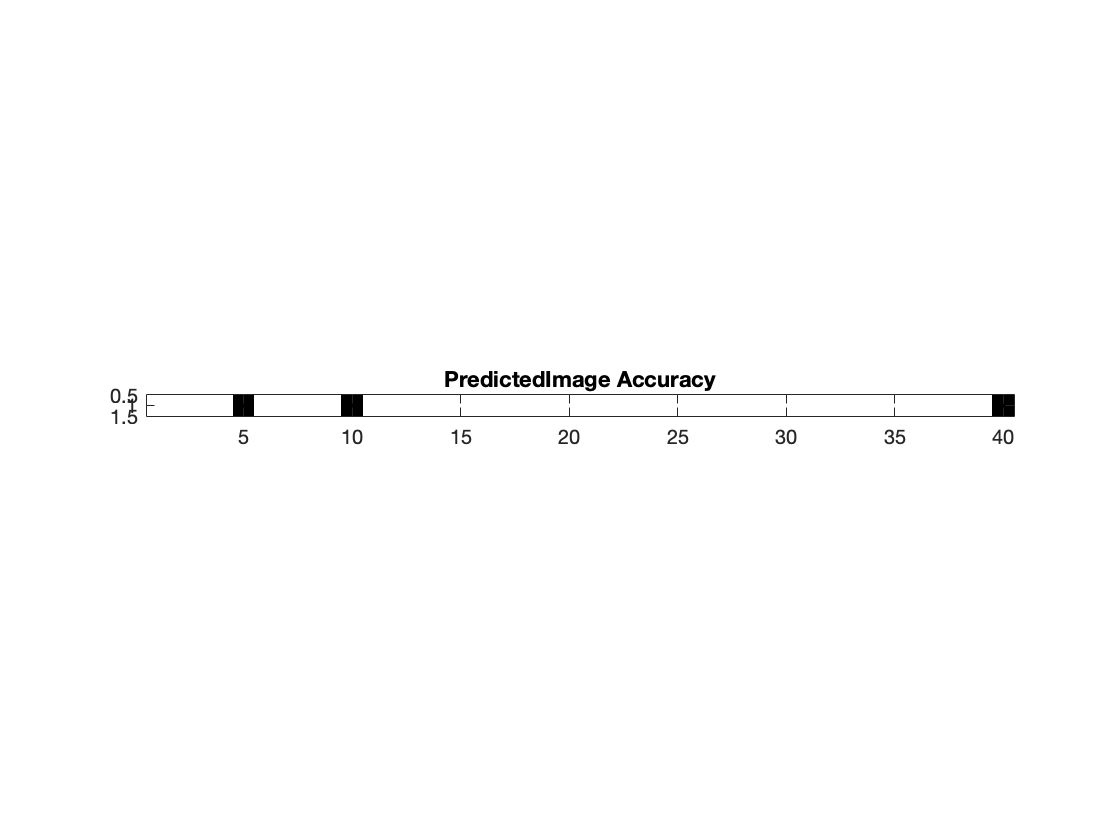



for i = 1:40
    lower_end = (i-1)*9;
    upper_end = i*9;
    index_result = results(i);
    if index_result <= upper_end
        if index_result > lower_end        
            results_plot(i) = true;
            %disp('1')
        else    
            results_plot(i) = false;
            %disp('2')
        end
    else
        esults_plot(i) = false;
        %disp('3')
    end    
end    
figure(10);
imagesc(results_plot), axis image, colormap gray, title("PredictedImage Accuracy");

disp('the results matrix save the most similiar photo number to each test photo')

the results matrix save the most similiar photo number to each test photo


disp('for the results_plot, it save whether the prediction is correct or not') 

for the results_plot, it save whether the prediction is correct or not


disp('in here I use 360 for dimensionality, which can give a better prediction') 

in here I use 360 for dimensionality, which can give a better prediction


disp('in the picture, white means prediction is correct, black is false.')

in the picture, white means prediction is correct, black is false.


9. Show the closest image in the training dataset for the $s_1$ test example.

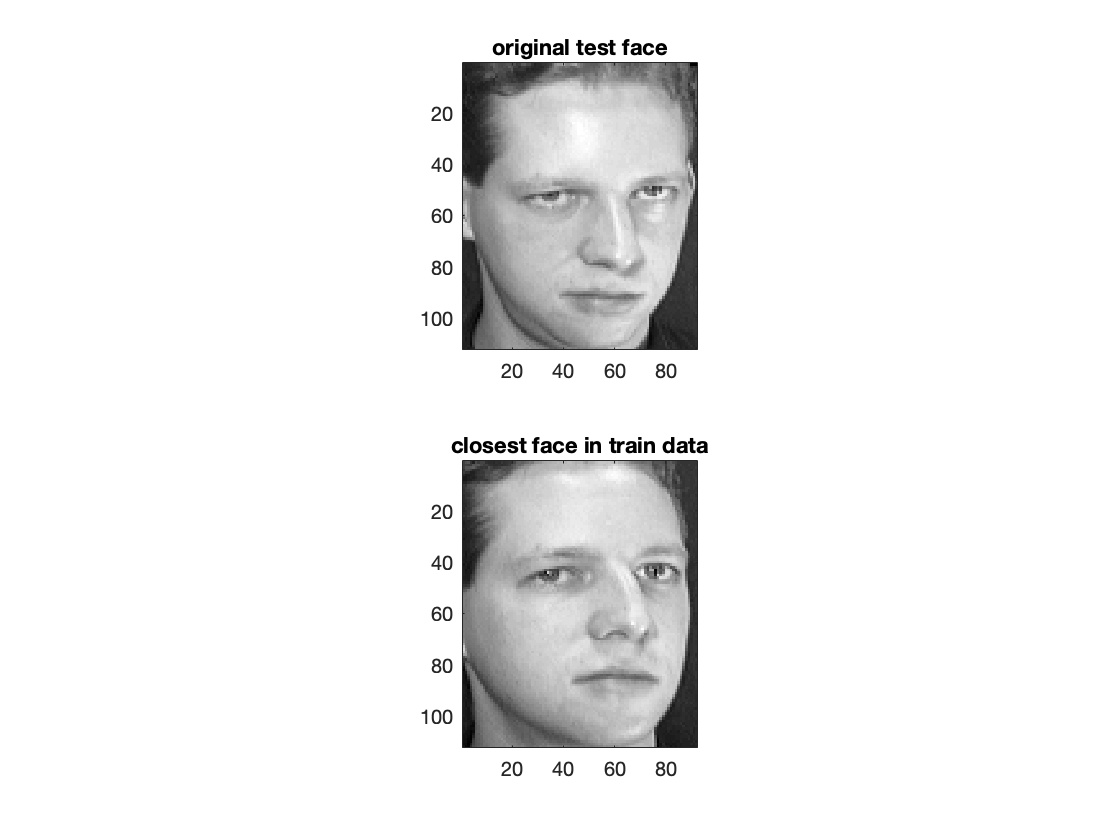

% Your code goes here
figure(9)
subplot(2,1,1)
imagesc(reshape(test_data(1,1,:), 112,92)), axis image, colormap gray, title(['original test face']);
subplot(2,1,2)
imagesc(reshape(train_data(1,results(1,1),:), 112,92)), axis image, colormap gray, title(['closest face in train data']);

disp('this is the closest face in train to the test')

this is the closest face in train to the test
